## **3.a.**

prob_states = zeros(1,5);
states = [10^-6 10^-5 10^-4 10^-3 10^-2];

pi = 1 + 8/600 + 8/600 * 5/100 + 8/600 * 5/100 * 2/20 + 8/600 * 5/100 * 2/20 * 1/5;
prob_states(1) = 1 / pi;
prob_states(2) = (8/600) / pi;
prob_states(3) = (8/600 * 5/100) / pi;
prob_states(4) = (8/600 * 5/100 * 2/20) / pi;
prob_states(5) = (8/600 * 5/100 * 2/20 * 1/5) / pi;

fprintf('%.2e (10^-6), %.2e (10^-5), %.2e (10^-4), %.2e (10^-3), %.2e (10^-2)', prob_states);

9.86e-01 (10^-6), 1.31e-02 (10^-5), 6.57e-04 (10^-4), 6.57e-05 (10^-3), 1.31e-05 (10^-2)

## **3.b.**

% A probabilidade de um link estar num determinado estado é igual à
% percentagem de tempo médio que cada link fica nesse estado.
fprintf('%.2e (10^-6), %.2e (10^-5), %.2e (10^-4), %.2e (10^-3), %.2e (10^-2)', prob_states);

9.86e-01 (10^-6), 1.31e-02 (10^-5), 6.57e-04 (10^-4), 6.57e-05 (10^-3), 1.31e-05 (10^-2)

## **3.c.**

average_ber = sum(prob_states .* states);
fprintf('%.2e', average_ber);

1.38e-06

## **3.d.**

time_states = zeros(1,5);

time_states(1) = 1 / 8;
time_states(2) = 1 / (5 + 600);
time_states(3) = 1/(100 + 2);
time_states(4) = 1/(20 + 1);
time_states(5) = 1/5;

fprintf('%.2e (10^-6), %.2e (10^-5), %.2e (10^-4), %.2e (10^-3), %.2e (10^-2)', time_states * 60);

7.50e+00 (10^-6), 9.92e-02 (10^-5), 5.88e-01 (10^-4), 2.86e+00 (10^-3), 1.20e+01 (10^-2)

## **3.e.**

prob_states_normal = sum(prob_states(1:3));
prob_states_interference = sum(prob_states(4:5));

fprintf('%.6f (normal), %.2e (interference)', prob_states_normal, prob_states_interference);

0.999921 (normal), 7.89e-05 (interference)

## **3.f.**

average_ber_normal = sum(prob_states(1:3) .* states(1:3))/prob_states_normal;
average_ber_interference = sum(prob_states(4:5) .* states(4:5))/prob_states_interference;

fprintf('%.2e (normal), %.2e (interference)', average_ber_normal, average_ber_interference);

1.18e-06 (normal), 2.50e-03 (interference)

## **3.g.**

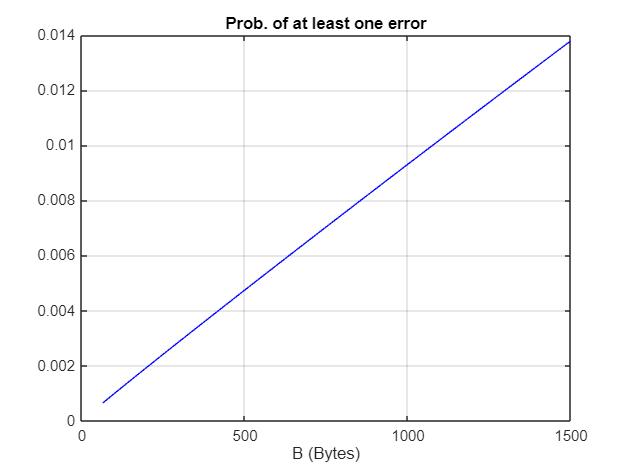

x = 64:1500;
bits = 8;
prob_error = zeros(5, length(x));

for i = 1 : 5
    prob_error(i, 1:length(x)) = 1 - (1 - states(i)).^(x.*bits);
end

error = prob_error(1, 1:length(x)).*prob_states(1) + prob_error(2, 1:length(x)).*prob_states(2) + prob_error(3, 1:length(x)).*prob_states(3) + prob_error(4, 1:length(x)).*prob_states(4) + prob_error(5, 1:length(x)).*prob_states(5);

figure;
plot(x, error, 'b');
xlabel('B (Bytes)');
title('Prob. of at least one error');
grid on;

% á medida que o tamanho do pacote aumenta, a probabilidade de pelo menos
% um erro também aumenta. isso ocorre porque, quanto maior for o pacote,
% mais bits estão a ser transmitidos, aumentando as chances de um bit ter
% um erro.

## **3.h.**

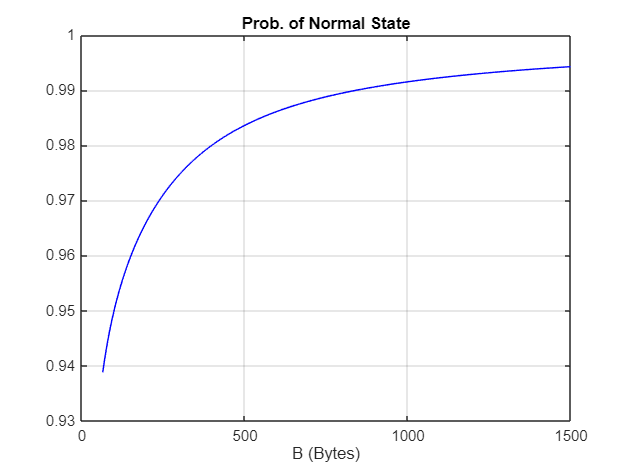

error_normal = (prob_error(1, 1:length(x)) .* prob_states(1) + prob_error(2, 1:length(x)) .* prob_states(2) + prob_error(3, 1:length(x)) .* prob_states(3)) ./ (prob_error(1, 1:length(x)) .* prob_states(1) + prob_error(2, 1:length(x)) .* prob_states(2) + prob_error(3, 1:length(x)) .* prob_states(3) + prob_error(4, 1:length(x)) .* prob_states(4) + prob_error(5, 1:length(x)) .* prob_states(5));

figure;
plot(x, error_normal, 'b');
xlabel('B (Bytes)');
title('Prob. of Normal State');
grid on;

% Tal como se pode ver pel

## **3.i.**

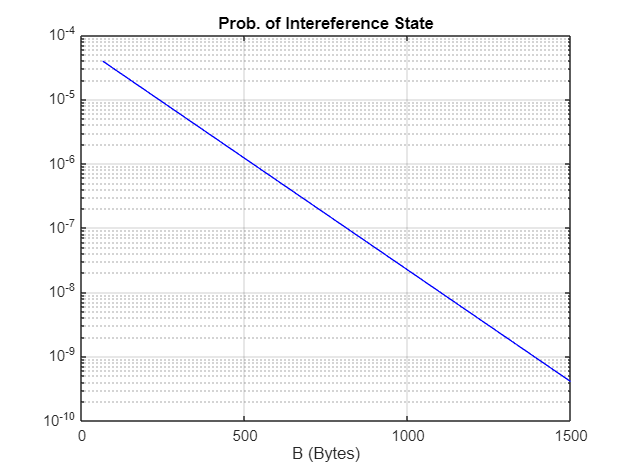

prob_without_errors = zeros(5, length(x));

for i = 1 : 5
    prob_without_errors(i, 1:length(x)) = (1 - states(i)).^(x.*bits);
end

error_interfece = (prob_without_errors(4, 1:length(x)) .* prob_states(4) + prob_without_errors(5, 1:length(x)) .* prob_states(5)) ./ (prob_without_errors(1, 1:length(x)) .* prob_states(1) + prob_without_errors(2, 1:length(x)) .* prob_states(2) + prob_without_errors(3, 1:length(x)) .* prob_states(3) + prob_without_errors(4, 1:length(x)) .* prob_states(4) + prob_without_errors(5, 1:length(x)) .* prob_states(5));

figure;
semilogy(x, error_interfece, 'b');
xlabel('B (Bytes)');
title('Prob. of Intereference State');
grid on;